load('net.mat')

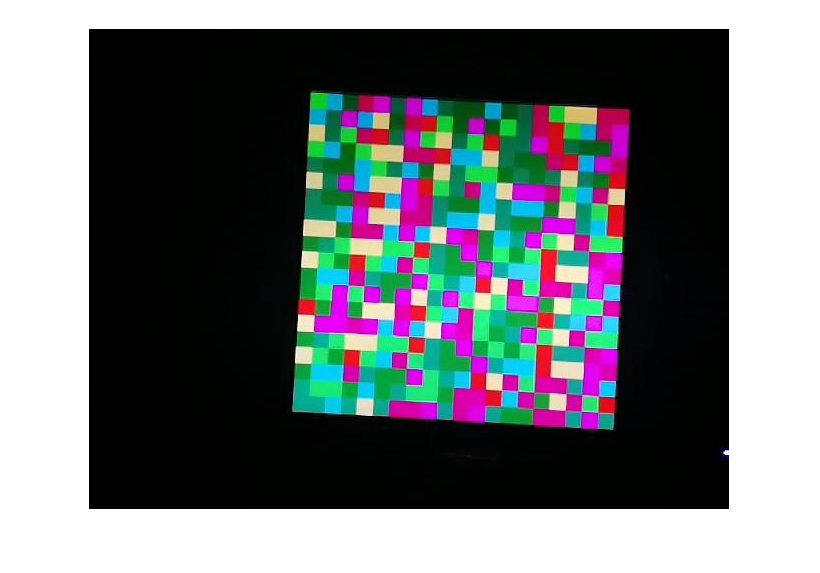

img = (imread('../Training data/1.jpg'));
imshow(img);

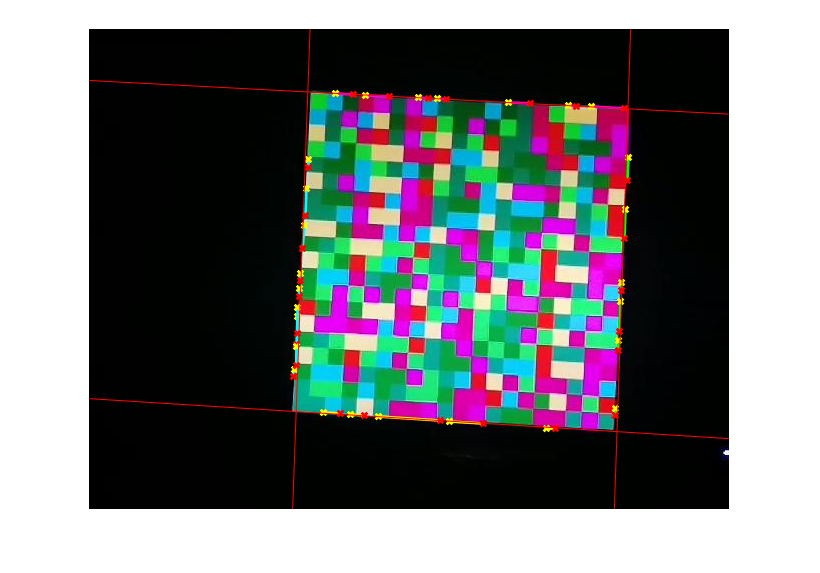

vertices =   207.6780  383.0722
  219.2963   63.4647
  528.5155  403.1247
  539.4550   80.3166


corners =   207.6780  383.0722
  219.2963   63.4647
  528.5155  403.1247
  539.4550   80.3166


corners=weighting(net,img,2)

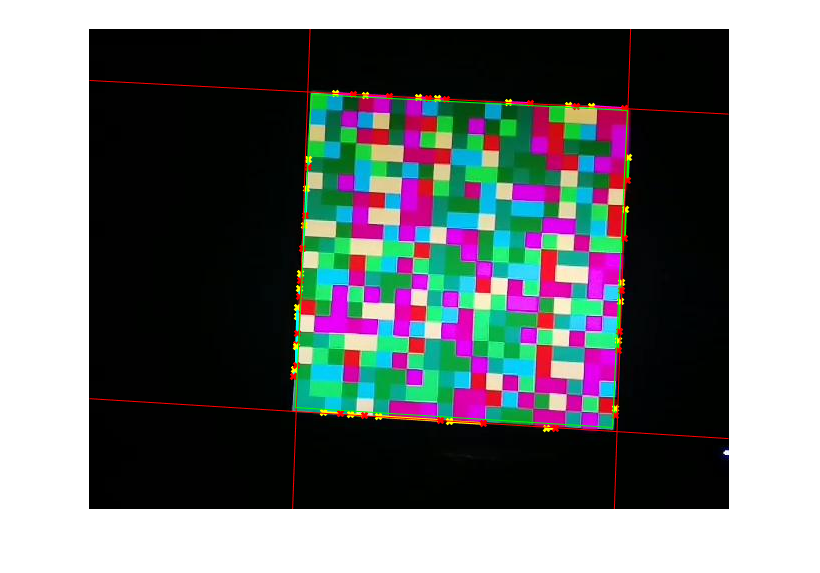

% Code to compare to previous method
% hold on
% C = semanticseg(img, net);
% featureMap = (C== 'Frame'); % Create a logical matrix of the feature map
% numberToExtract = 1;
% featureMap = ExtractNLargestBlobs(featureMap, numberToExtract);
% 
% 
% %% extract corners 
% K = (1/25)*ones(5); % smooth factor
% featureMap = conv2(featureMap,K,'same');
% 
% 
% [featureMap,J]=find(featureMap>max(featureMap(:))/2);
% IJ=[featureMap,J];  
% [~,idx]=min(IJ*[1 1; -1 -1; 1 -1; -1 1].');
% corners=IJ(idx,:);
% y=corners(:,1);
% x=corners(:,2);
% plot([x(1) x(3)],[y(1) y(3)],'g')
% plot([x(2) x(4)],[y(2) y(4)],'g')
% plot([x(2) x(3)],[y(2) y(3)],'g')
% plot([x(1) x(4)],[y(1) y(4)],'g')

function vertices=weighting(semanticNet,img,numOrig)

C=semanticseg(img,semanticNet);
featureMap=(C=='Frame');
featureMap=(featureMap*255);


K = (1/25)*ones(5); % smooth factor
featureMap = conv2(featureMap,K,'same');
bwFeatureMap=edge(featureMap,'canny');

[H,T,R] = hough(bwFeatureMap);
P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
lines = houghlines(bwFeatureMap,T,R,P,'FillGap',5,'MinLength',7);
gradient=0;
aveX=0;
aveY=0;

for k = 1:length(lines)
    point1=lines(k).point1;
    point2=lines(k).point2;
    aveX=aveX+point1(1)+point2(1);
    aveY=aveY+point1(2)+point2(2);
    xy = [lines(k).point1; lines(k).point2];
    lines(k).dist=pdist(xy,"euclidean");
    gradient=((point1(2)-point2(2))/(0.0000000001+point1(1)-point2(1)));
    lines(k).gradient=gradient;
end

aveX=aveX/(2*length(lines));
aveY=aveY/(2*length(lines));
figure
imshow(img)
hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    point1=lines(k).point1;
    point2=lines(k).point2;
    gradient=lines(k).gradient;
    if abs(gradient)>1 && point1(1)>aveX
        lines(k).color='green';
    elseif abs(gradient)>1 && point1(1)<aveX
        lines(k).color='cyan';
    elseif abs(gradient)<1 && point1(2)<aveY
        lines(k).color='magenta';
    elseif abs(gradient)<1 && point1(2)>aveY
        lines(k).color='yellow';
    else
        'Not found'
    end
    %plot lines
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color',lines(k).color);
    % Plot beginnings and ends of lines
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
    hold on;
end

tab=struct2table(lines);
yArr=double(zeros(4,640));
sides=["green" "yellow" "cyan" "magenta"];
x=1:640;
hold on
for i=1:4
    color=sides(i);
    rows=ismember(tab.color,color);
    tabTemp=tab(rows,:);
    if numOrig>height(tabTemp)
        num=height(tabTemp);
    else num=numOrig;
    end

    tabTemp=sortrows(tabTemp,'dist','descend');
    tabTemp=tabTemp(1:num,:);
    gradient=0;
    sumWeight=0;
    pointX=0;
    pointY=0;
    for j=1:height(tabTemp)
        weight=tabTemp(j,:).dist/tabTemp(1,:).dist;
        sumWeight=sumWeight+weight;
        gradient=gradient+weight*tabTemp(j,:).gradient;
        pointX=pointX+weight*(tabTemp(j,:).point1(1)+tabTemp(j,:).point2(1));
        pointY=pointY+weight*(tabTemp(j,:).point1(2)+tabTemp(j,:).point2(2));
    end
    gradient=gradient/sumWeight;
    
    
    pointX=pointX/(2*sumWeight);
    pointY=pointY/(2*sumWeight);
    
    b=pointY-gradient*pointX;
    y=polyval([gradient b],x);
    yArr(i,:)=y;
    plot(x,y,'r')
    hold on
end
hold on

curve=[x;yArr(1,:);x;yArr(2,:);x;yArr(3,:);x;yArr(4,:)];
vertices=double(zeros(4,2));
iteration=1;
for i=1:3
    for j=i:3

        P=InterX(curve(2*i-1:2*i,:),curve(1+2*j:2+2*j,:));
        if length(P)>0 && P(1)<640 && P(2)<480
            vertices(iteration,:)=P;
            iteration=iteration+1;
        end
    end
end
vertices=sortrows(vertices,[1 2])
end


